Color_1 = [0 0.4470 0.7410];
Color_2 = [0.8500 0.3250 0.0980];
Color_3 = [0.9290 0.6940 0.1250];
Color_4 = [0.4940 0.1840 0.5560];
Color_5 = [0.4660 0.6740 0.1880];
Color_6 = [0.3010 0.7450 0.9330];
Color_7 = [0.6350 0.0780 0.1840];

syms t x y mu eta real
f = [
    eta*x*(1 - eta*x/2) - x*y
    y*(mu - y) - x*y
    ];
x = [x;y];

f_fh = matlabFunction(f,'vars',{x,mu,eta});             % later used for ODE solver
J_fh = matlabFunction(jacobian(f,x),'vars',{x,mu,eta}); % compute trace and determinant of Jacobian
f1_fh = matlabFunction(f(1),'vars',[x;mu;eta]);         % to plot vector field
f2_fh = matlabFunction(f(2),'vars',[x;mu;eta]);         % to plot vector field

Egy másik reprezentációja a Lotka-Volterra egyenletnek:


$$\left\{ \begin{array}{l}  
\dot x_1 = x( a_{11} x_1 + a_{12} x_2 + b_1)
\\
\dot x_2 = y( a_{21} x_1 + a_{22} x_2 + b_2)
\end{array} $$


Mátrix-vektor formában felírva a következő egyenletet kapjuk:

$\dot x = x \odot ( A x + b )$,

ahol az $\odot$ szimbólum a Hadamard (vagyis az elemenkénti) mátrix szorzatot jelöli. Ez a forma azért előnyös mert ebből könnyedén kifejezhető az egyetlen nemnulla egyensúlyi pont: 

$x^* = - A^{-1} b$.

A = sym('a',[2,2]), b = sym('b',[2,1]);

$$A = \left(\begin{array}{cc} a_{1,1} & a_{1,2}\\ a_{2,1} & a_{2,2} \end{array}\right)$$

EqP = simplify(-A \ b)

$$EqP = \left(\begin{array}{c} \frac{a_{1,2}\,b_{2}-a_{2,2}\,b_{1}}{a_{1,1}\,a_{2,2}-a_{1,2}\,a_{2,1}}\\ -\frac{a_{1,1}\,b_{2}-a_{2,1}\,b_{1}}{a_{1,1}\,a_{2,2}-a_{1,2}\,a_{2,1}} \end{array}\right)$$

A következő két sorban $\dot x = f(x)$ formából fejezem ki A és b értékeit.

A_ = jacobian( simplify(f ./ x) , x )

$$A\_ = \left(\begin{array}{cc} -\frac{\eta^{2}}{2} & -1\\ -1 & -1 \end{array}\right)$$

b_ = simplify( (f - A_*x .* x) ./ x )

$$b\_ = \left(\begin{array}{c} \eta \\ \mu \end{array}\right)$$

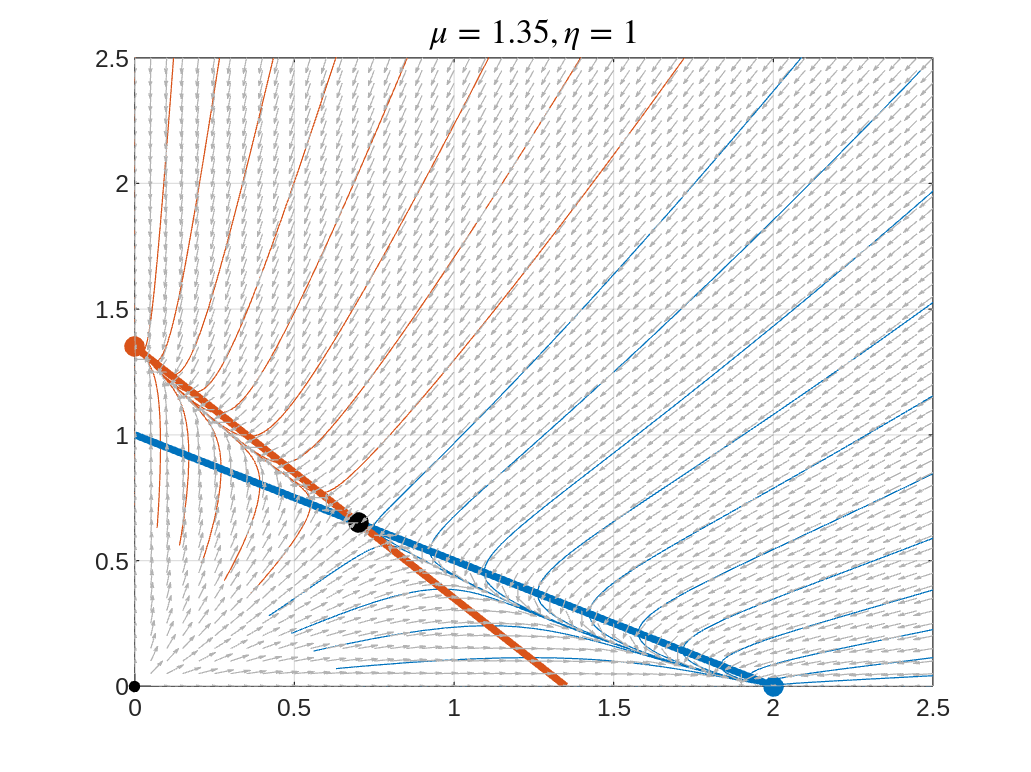

LimX = 2.5;
LimY = 2.5;
hX = 0.05;
hY = 0.05;

mu = 1.35;
eta = 1;

A = double(subs(A_));
b = double(subs(b_));

Color_X = Color_1;
Color_Y = Color_2;
Color_P = [0 0 0] * 0.2;

EqX = [-b(1)/A(1,1) ; 0];
EqY = [0 ; -b(2)/A(2,2)];
EqP = -A \ double(subs(b));

fig = figure(123);
delete(fig.Children);
ax = axes(fig); hold on; grid on; box on

Pl_ode = [];
for alpha = 0:0.1:1
    x0 = [alpha ; 1-alpha]*0.7;
    [t,x] = ode45(@(t,x) f_fh(x,mu,eta),[0 10],x0);
    Pl = plot(x(:,1),x(:,2));
    Pl.UserData.x0 = x0;
    Pl.UserData.xEnd = x(end,:)';
    if isempty(Pl_ode)
        Pl_ode = Pl;
    else
        Pl_ode = [Pl_ode , Pl];
    end
end

for alpha = 0:0.05:1
    x0 = [alpha ; 1-alpha]*5;
    [t,x] = ode45(@(t,x) f_fh(x,mu,eta),[0 10],x0);
    Pl = plot(x(:,1),x(:,2));
    Pl.UserData.x0 = x0;
    Pl.UserData.xEnd = x(end,:)';
    Pl_ode = [Pl_ode , Pl];
end

for Pl = Pl_ode
    if Pl.UserData.xEnd(1) < EqP(1)
        Pl.Color = Color_Y;
    else
        Pl.Color = Color_X;
    end
end

plot(0,0,'k.','MarkerSize',14);
xx = linspace(0,EqX(1),2);
yy = -(b(1)+A(1,1)*xx)/A(2,1);
PlncX = plot(xx,yy,'Color',Color_X,'LineWidth',3);

yy = linspace(0,EqY(2),2);
xx = -(b(2)+A(2,2)*yy)/A(1,2);
PlncY = plot(xx,yy,'Color',Color_Y,'LineWidth',3);

PleX = plot(EqX(1),EqX(2),'.','Color',Color_X,'MarkerSize',25);
PleY = plot(EqY(1),EqY(2),'.','Color',Color_Y,'MarkerSize',25);
PleP = plot(EqP(1),EqP(2),'.','Color',Color_P,'MarkerSize',25);

% Compute the values of the vector field in a given number of grid points.
[xx,yy] = meshgrid(0:hX:LimX,0:hY:LimY);
f1_val = f1_fh(xx,yy,mu,eta);
f2_val = f2_fh(xx,yy,mu);

% Normalize the vectors of the vector field.
r = sqrt(f1_val.^2 + f2_val.^2);
f1_val = f1_val ./ r;
f2_val = f2_val ./ r;

% Visualize the normalized vector field.
Qv = quiver(xx,yy,f1_val,f2_val,'Color',[1,1,1]*0.7);

Tit = title("$\mu = " + num2str(mu) + ", \eta = " + num2str(eta) + "$",'Interpreter','latex','FontSize',14);
xlim([0 LimX])
ylim([0 LimY])

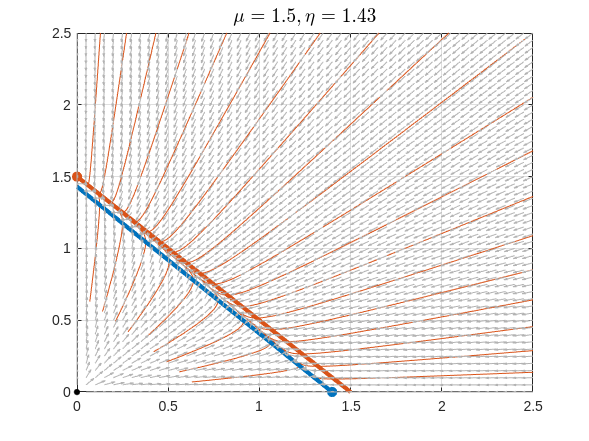

mu = 1.5;
eta_vals = 1:0.01:2;
for i = 1:numel(eta_vals)
    eta = eta_vals(i);
    A = double(subs(A_));
    b = double(subs(b_));
    
    EqX = [-b(1)/A(1,1) ; 0];
    EqY = [0 ; -b(2)/A(2,2)];
    EqP = -A \ double(subs(b));
    
    PlncX.XData = linspace(0,EqX(1),2);
    PlncX.YData = -(b(1)+A(1,1)*PlncX.XData)/A(2,1);
    
    PlncY.YData = linspace(0,EqY(2),2);
    PlncY.XData = -(b(2)+A(2,2)*PlncY.YData)/A(1,2);

    PleX.XData = EqX(1);
    PleX.YData = EqX(2);

    PleY.XData = EqY(1);
    PleY.YData = EqY(2);

    PleP.XData = EqP(1);
    PleP.YData = EqP(2);
    if all(EqP > 0)
        PleP.Visible = "on";
    else
        PleP.Visible = "off";
    end
 
    for Pl = Pl_ode
        [t,x] = ode45(@(t,x) f_fh(x,mu,eta),[0 50],Pl.UserData.x0);
        Pl.XData = x(:,1);
        Pl.YData = x(:,2);
        [~,idx] = min(vecnorm(x(end,:)' - [EqX,EqY,EqP],2,1));
        switch idx
            case 1
                Pl.Color = Color_X;
            case 2
                Pl.Color = Color_Y;
            case 3
                Pl.Color = Color_P;
        end
    end
    
    % Compute the values of the vector field in a given number of grid points.
    [xx,yy] = meshgrid(0:hX:LimX,0:hY:LimY);
    f1_val = f1_fh(xx,yy,mu,eta);
    f2_val = f2_fh(xx,yy,mu,eta);
    
    % Normalize the vectors of the vector field.
    r = sqrt(f1_val.^2 + f2_val.^2);
    f1_val = f1_val ./ r;
    f2_val = f2_val ./ r;
    
    % Visualize the normalized vector field.
    Qv.XData = xx;
    Qv.YData = yy;
    Qv.UData = f1_val;
    Qv.VData = f2_val;

    Tit.String = "$\mu = " + num2str(mu) + ", \eta = " + num2str(eta) + "$";

    drawnow
    pause(0.1)
end

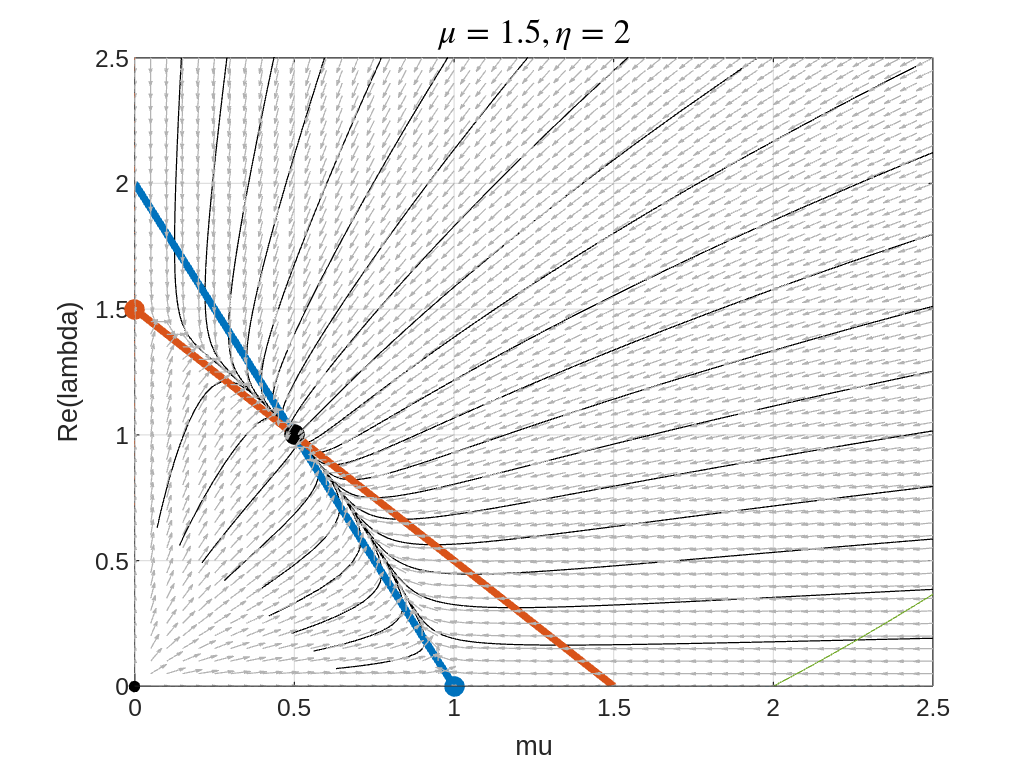

mu_vals = 0.5:0.01:2.5;
Eigs = nan(2,numel(mu_vals));
for i = 1:numel(mu_vals)
    mu = mu_vals(i);
    EqP = -A \ double(subs(b));
    J_EqP = J_fh(EqP,mu,eta);
    Eigs(:,i) = eig(J_EqP);
end
Eigs = switch_Eigs(Eigs);

fig = figure(31); 
delete(fig.Children)
fig.Visible = 'on';
hold on; box on;
plot3(mu_vals,real(Eigs(1,:)),imag(Eigs(1,:)))
plot3(mu_vals,real(Eigs(2,:)),imag(Eigs(2,:)))
yline(0)
xlabel('mu')
ylabel('Re(lambda)')
zlabel('Im(lambda)')

function Eigs = switch_Eigs(Eigs)
    n = height(Eigs);
    dim = zeros(1,n);
    for i = 1:width(Eigs)-1
        for d = 1:n
            [~,dim(d)] = min(abs(Eigs(d,i) - Eigs(:,i+1)));
        end
        if any(dim ~= 1:n) && all(sort(dim) == 1:n)
            Eigs(:,i+1:end) = Eigs(dim,i+1:end);
        end
    end
end